# 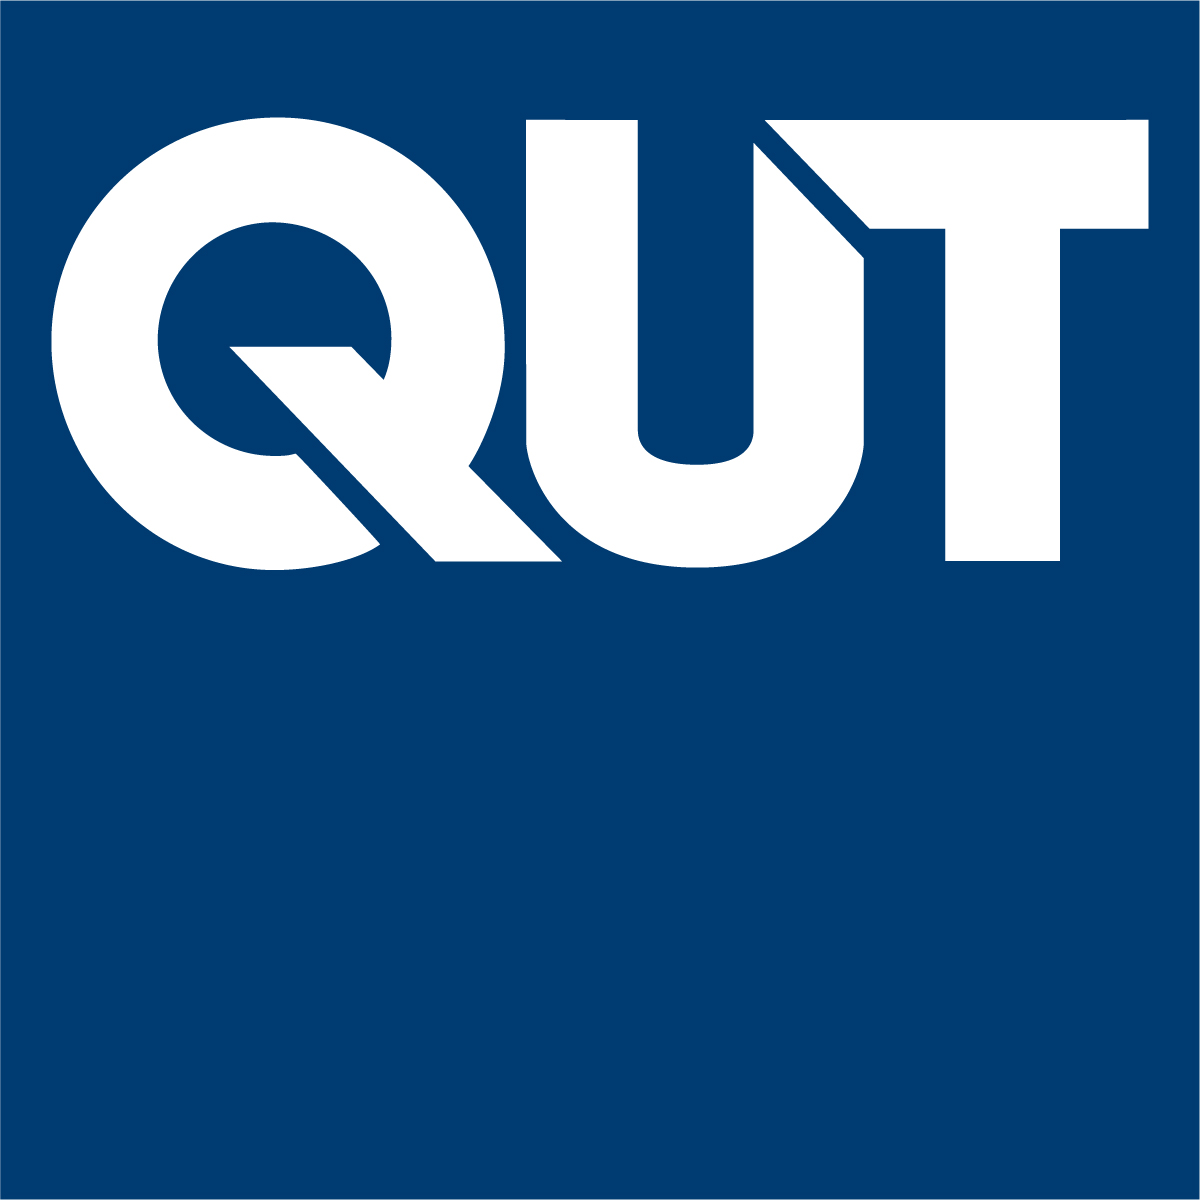

# MXB201 Linear Algebra in the Real World™ Series

Professor Tim Moroney,  2022

V1.0

## Principal component analysis

Linear Algebra prerequisites:

- Singular value decomposition

Principal Component Analysis (PCA) refers to the application of the Singular Value Decomposition to reduce the dimensionality of a problem while preserving as much information as possible.  There are different flavours of PCA, which can be applied in subtly different ways across fields of applied mathematics, statistics, machine learning and computer vision.  In this worksheet, as in your group project, the application of PCA will be to a "tall matrix", with the goal being to find more compact, but only approximate, representations of that matrix's columns.

In part II of your project, the application is to eigenfaces, where each column represents a reshaped two-dimensional greyscale image.  In this worksheet, each column will represent the profile of a taut string, like a guitar string, as it vibrates after being plucked.

Mathematically, the profile of the string is just a function $y(x)$, where $y$ represents the string's displacement, and $x$ is the spatial coordinate between 0 and 1.  The string is held fixed at both ends $x = 0$ and $x = 1$, just like in a guitar or similar instrument.

We begin by pulling the string up at (for the sake of picking somewhere) $x = 0.3$.  The moment we release the string, it will begin its vibration.

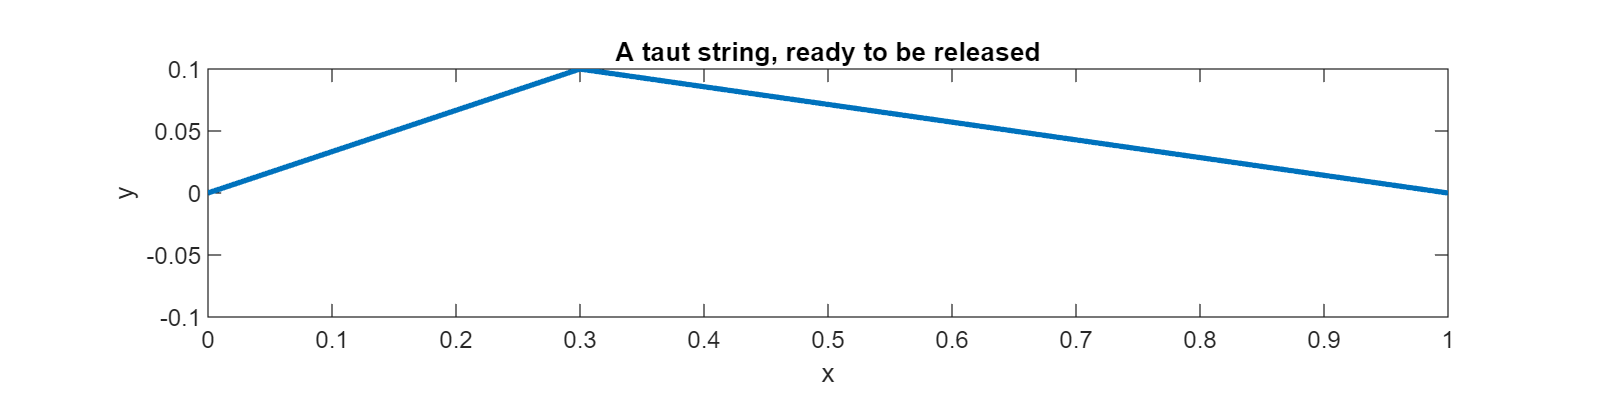

clear
load string
figure('Position', [1 1 800 200])
plt = plot(x, Adamp(:,1), 'LineWidth', 2);
axis image
ylim([-0.1,0.1])
title('A taut string, ready to be released')
xlabel x, ylabel y

Suppose we have a high-speed camera capturing the profile of the string at a sufficiently high frame rate that we can resolve individual frames within a single cycle of the string.  The array `Adamp` is a matrix of such frames, which has 1000 rows and 600 columns.

Adamp

Adamp =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0002    0.0002    0.0001    0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001 

Each column of `Adamp` represents the actual $y$-profile of the string for some particular point in time.  So the first column, `Adamp(:,1)`, gives the image we plotted above.

Adamp(:,1)

ans =          0
    0.0003
    0.0007
    0.0010
    0.0013
    0.0017
    0.0020
    0.0023
    0.0027
    0.0030


Each column of `Adamp` has 1000 entries, corresponding to 1000 equally spaced $x$-values between 0 and 1.

x

x =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


Altogether there are 600 frames, meaning the string profile has been captured at 600 discrete points in time, equally spaced temporally.

Side note: when solving these sort of time/space problems, there's always the question of whether each snapshot in time should be a row, or a column.  For this worksheet, we've made them columns.  This is consistent with your group project Part II.

We could animate the string's vibration by just playing these 600 frames (columns) in sequence.

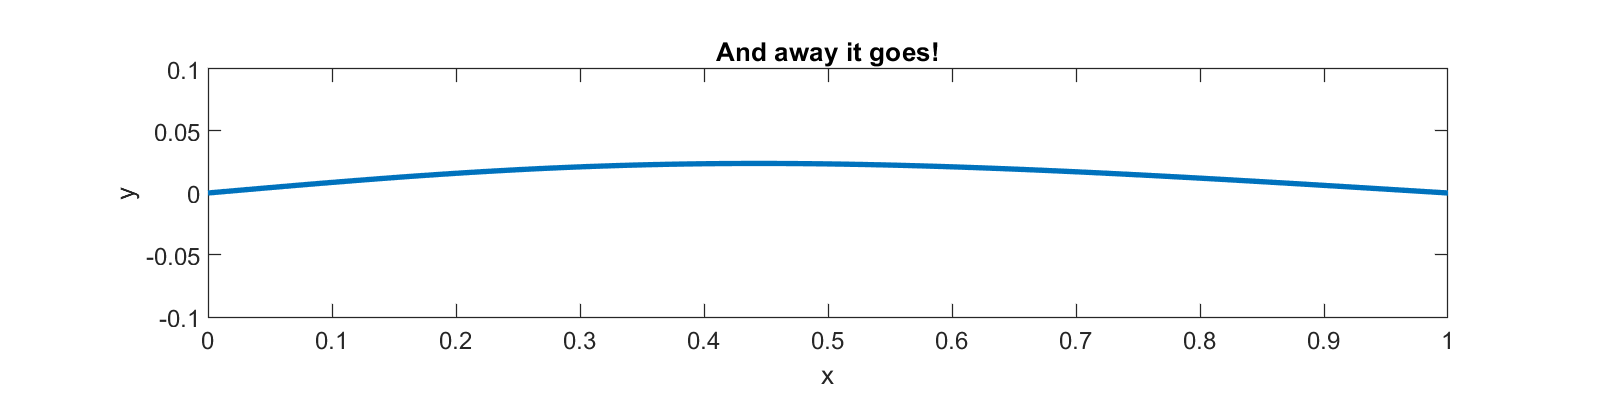

title('And away it goes!')
pause(1)
for j = 1:4:size(Adamp, 2) % plot every 4th frame
    plt.YData = Adamp(:,j);
    drawnow
end

## **But let's not run before we can walk**

The animation above is reasonably realistic, in the way that the string gradually loses energy: its motion is *damped*.  After only a few cycles, its displacement is only a small fraction of the initial displacement.

But to begin with, we will actually analyse the motion of a very idealised string undergoing *un*damped motion.  Without damping, the string never loses energy, so after one cycle it returns exactly back to where it started, ready to repeat the process over again exactly the same.  Hence, it's only necessary to visualise one full cycle of the vibrating string without damping.

These frames are recorded in the array `Anodamp`, which has only 200 frames, corresponding to one full cycle.

Anodamp

Anodamp =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.000

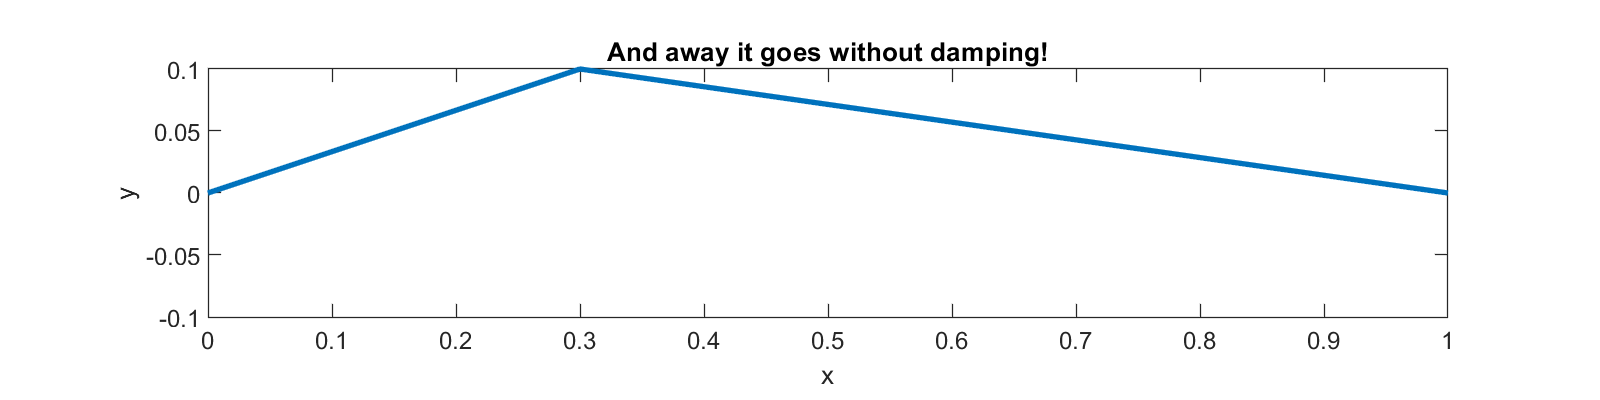

title('And away it goes without damping!')
pause(1)
for j = [1:4:size(Anodamp, 2) 1] % plot every 4th frame
    plt.YData = Anodamp(:,j);
    drawnow
end

The question that Principal Component Analysis asks is: can the Singular Value Decomposition compactly represent the essential information in this matrix $A$?  If so, we might hope that this compact representation gives us some clue as to what physics is going on with this vibrating string.  That is, it might help us get at the *essence* of what all the data in the matrix `Anodamp` are trying to tell us.

`Anodamp` is a tall matrix, just like we're used to dealing with in Chapter 5, with 1000 rows and 200 columns.

Anodamp

Anodamp =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.000

So it's natural to find its reduced SVD $A = U \Sigma V^T$.  Let's do that now.

[U,Sigma,V] = svd(Anodamp, 'econ')

U =    -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
   -0.0001    0.0003    0.0007   -0.0006    0.0004   -0.0008    0.0011   -0.0012   -0.0015    0.0015    0.0010   -0.0020    0.0017    0.0024    0.0019    0.0025    0.0027   -0.0019    0.0024   -0.0031   -0.0032   -0.0024   -0.0029    0.0031    0.0040   -0.0031    0.0027    0.0045    0.0039    0.0032   -0.0034   -0.0049   -0.0037   -0.0042   -0.0050    0.0040   -0.0036    0.0037   -0.0048   -0.0051   -0.0033   -0.0062   -0.0046    0.0061    0.0016    0.0033   -0.0049    0.0048   -0.0044   -0

Sigma =    17.4477         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    5.1278         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

V =    -0.1000    0.1000   -0.1001    0.1000    0.0999    0.1002    0.0997   -0.0999    0.1054   -0.0952    0.0983   -0.0991    0.1056   -0.0937    0.1058   -0.0939    0.1000   -0.1179   -0.0673    0.0925   -0.0978    0.1060    0.0992    0.0980   -0.0846    0.0967   -0.0833    0.0700   -0.0871    0.1029   -0.1064    0.0650   -0.0883    0.0666   -0.0645    0.0763   -0.0912    0.0493    0.0738   -0.0782   -0.0493    0.0722    0.0663   -0.0853   -0.0532   -0.0468   -0.0522   -0.0524    0.0568    0.0759
   -0.0998    0.0992   -0.0952    0.0968    0.0981    0.0931    0.0872   -0.0842    0.0807   -0.0689    0.0889   -0.0572    0.0644   -0.0368    0.0529   -0.0306    0.0149   -0.0365   -0.0568   -0.0078    0.0274    0.0402   -0.0077   -0.0422    0.0535   -0.0199    0.0506   -0.0638    0.0874   -0.0069    0.1340   -0.0682    0.0711   -0.1019    0.0766   -0.0636    0.0300   -0.1008   -0.1226    0.1229    0.0821   -0.1105   -0.0829    0.1028    0.0079    0.0770    0.0776    0.0674   -0.0868   -0

Straight away we can notice something promising: the singular values on the diagonal of $\Sigma$ are dying off reasonably quickly.  Let's take a closer look:

sigma = diag(Sigma)

sigma =    17.4477
    5.1278
    0.8628
    0.7923
    0.7405
    0.3522
    0.3206
    0.2155
    0.1443
    0.1425


So it looks like we could get a pretty decent reconstruction of `Adamp` using just the first, say, 6 singular values and vectors.  Let's call this matrix `Adamp` just $A$ for now, while we develop the mathematics.

Clearly you can make the cutoff at different places, but let's just say we think that the first 6 singular values and vectors are sufficient.  If that's the case, then what we're saying is that each column of $A$ is approximately a linear combination of just the first 6 *left *singular vectors (the columns of $U$).

So let's see about that.   Take the first column of $A$.  We know it represents the string profile at time zero.

Evidently, this profile can be approximated by a linear combination of the first 6 columns of $U$.  What linear combination?  The SVD gives us the exact representation of $A$:


$$A = U \Sigma V^T$$


but also the best rank-$\nu$ *approximation* to $A$ by just using the first $\nu$ singular values and vectors:

$\tilde{A}$ $= U$`(:, 1:`$\nu$`) `$\Sigma$`(1:`$\nu$`, 1:`$\nu$`) `$V$`(:, 1:`$\nu$`)`$^T$

In terms of a particular column of $\tilde{A}$, we therefore have

$\tilde{A}$`(:,j)` $= U$`(:, 1:`$\nu$`) `$\Sigma$`(1:`$\nu$`, 1:`$\nu$`) `$V$`(j, 1:`$\nu$`)`$^T$

Which is another way of saying that $\tilde{A}$`(:,j)` is 

$\tilde{A}$`(:,j)` $= U$`(:, 1:`$\nu$`) `$c_j$

where $c_j$ is the coordinate vector of $A$`(:,j)` projected onto the orthonormal basis $\textrm{span}\{u_1, u_2, \ldots u_\nu\}$.

Let's find the coordinate vector of the first column of $A$.

nu = 6;  % use the first six singular vectors
c1 = Sigma(1:nu, 1:nu) * V(1, 1:nu)'  % coordinate vector of A(:,1)

c1 =    -1.7448
    0.5128
   -0.0864
    0.0792
    0.0739
    0.0353


This is the coordinate vector of the first column of $A$ projected onto the ONB $\textrm{span}\{u_1, u_2, u_3, u_4, u_5, u_6\}$.

Let's see what this approximation of $A$`(:,1) `looks like.  On the left is $A$`(:,1)`, on the right is $U$`(:, 1:`$\nu$`) `$c_1$

[Anodamp(:,1) U(:, 1:nu)*c1]

ans =          0    0.0000
    0.0003    0.0003
    0.0007    0.0006
    0.0010    0.0009
    0.0013    0.0011
    0.0017    0.0014
    0.0020    0.0017
    0.0023    0.0020
    0.0027    0.0023
    0.0030    0.0026


The numerical values look pretty close!  Let's plot the approximation over the top of the string's true initial profile.

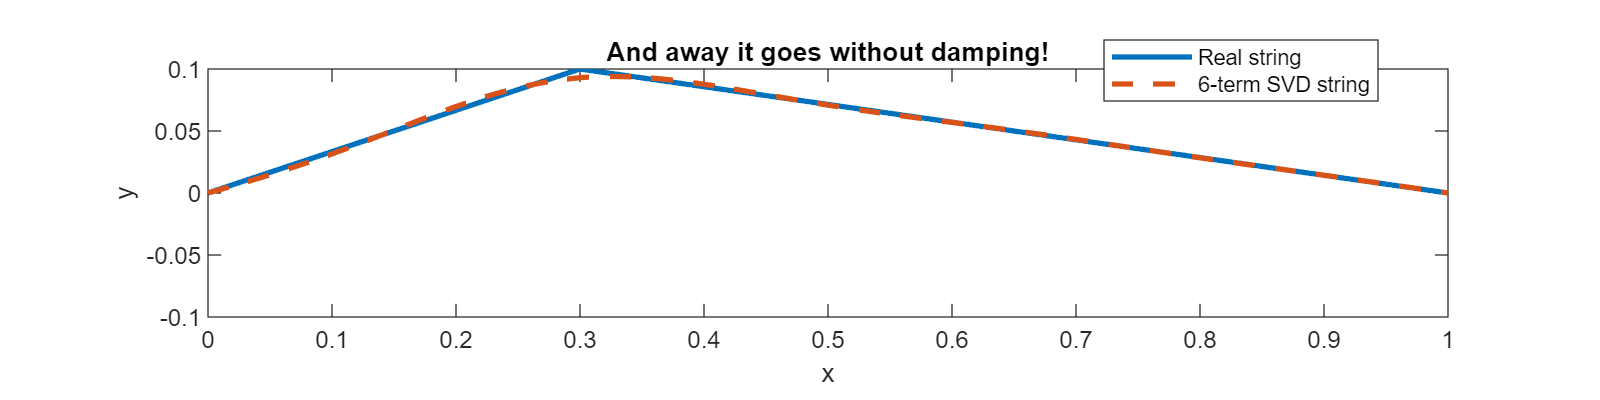

hold on
plot(x, U(:, 1:nu)*c1, '--', 'LineWidth', 2)  % initial profile of string
legend('Real string', '6-term SVD string', 'Location', 'best')

So that's interesting.  We have a slightly smoothed out string, built from (only) the first six columns of $U$.  But the SVD $A = U\Sigma V^T$ is a decomposition of the *whole* of $A$.  So whatever the first six singular vectors in $U$ are, they need to do a good job of representing *all* the frames in the animation with just a handful of vectors.

So we should be able to repeat this exercise with any column of $A$ and still get a good approximation to the string at that snapshot in time.

Let's take, say, column 80 of $A$.

Go ahead and find the coordinate vector of the projection of column 80 of $A$ onto the ONB $\textrm{span}\{u_1, u_2, u_3, u_4, u_5,u_6\}$.  Then plot that column, plus its 6-term SVD approximation, on a new figure.

c80 = Sigma(1:nu, 1:nu) * V(80, 1:nu)'

c80 =     1.4115
    0.1585
   -0.0862
   -0.0642
    0.0229
   -0.0285


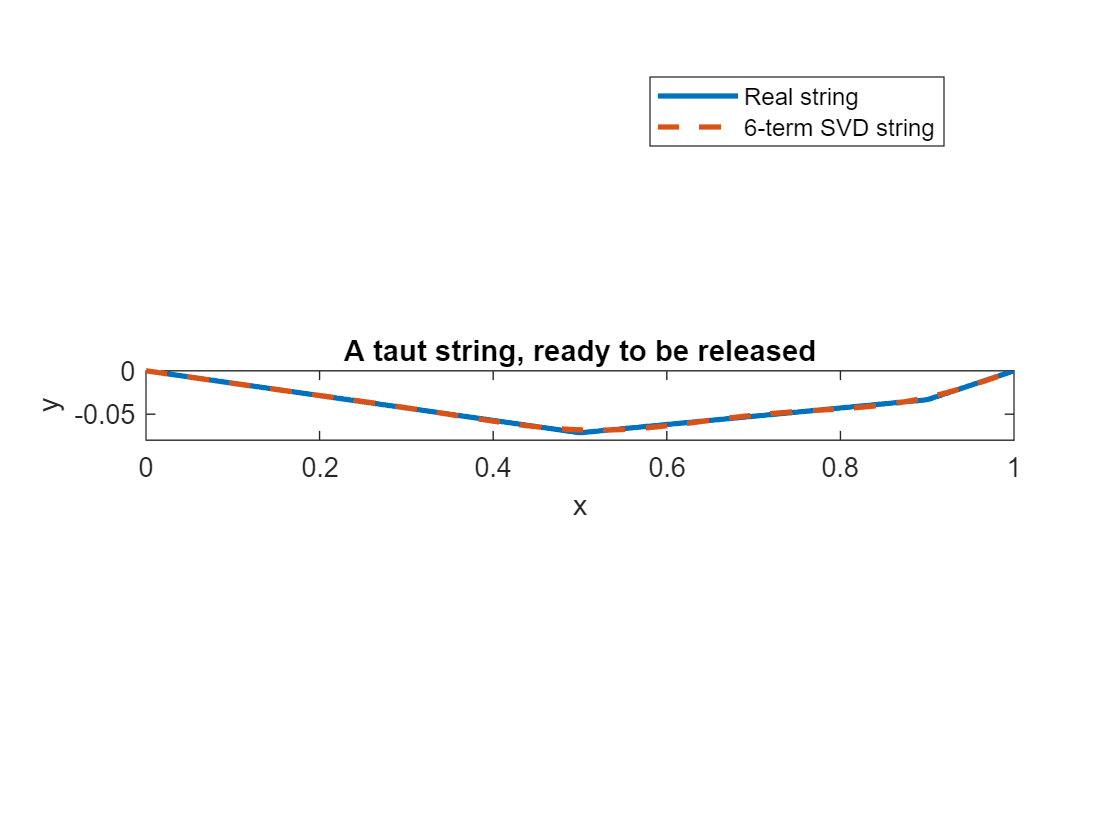

figure
plot(x, Anodamp(:,80), 'LineWidth', 2);
hold on
plot(x, U(:, 1:nu)*c80, '--', 'LineWidth', 2)  % profile of string at t=80
axis image
ylim([-0.08, 0])
title('A taut string, ready to be released')
legend('Real string', '6-term SVD string', 'Location', 'best')
xlabel x, ylabel y

You should find once again that the representation in terms of just the first 6 singular vectors is pretty good!

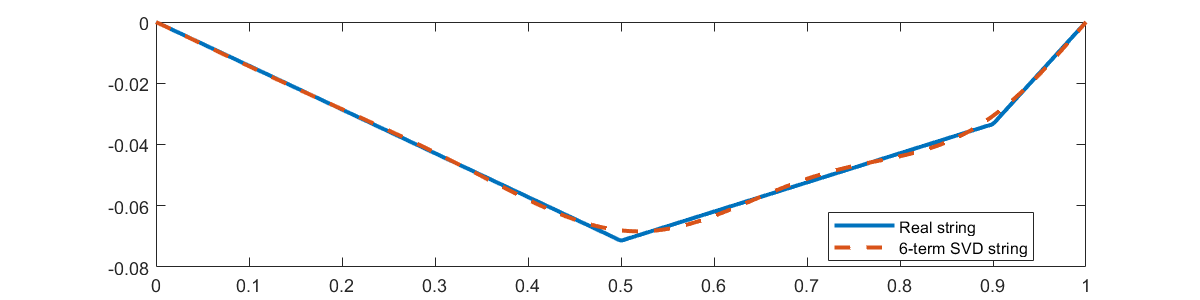

So evidently the first 6 columns of $U$ are pretty good at representing the profile of the string at *any* point in time; it's just a question of taking the correct linear combination.

What might be fun, is to actually *animate* the string using just these first 6 terms.

c_allframes = Sigma(1:nu, 1:nu) * V(:, 1:nu)'  % coordinate vectors of every column of A

c_allframes =    -1.7448   -1.7413   -1.7370   -1.7310   -1.7233   -1.7139   -1.7027   -1.6900   -1.6755   -1.6594   -1.6416   -1.6222   -1.6013   -1.5787   -1.5546   -1.5289   -1.5018   -1.4732   -1.4431   -1.4115   -1.3786   -1.3444   -1.3088   -1.2719   -1.2337   -1.1944   -1.1538   -1.1122   -1.0694   -1.0255   -0.9807   -0.9349   -0.8882   -0.8405   -0.7921   -0.7429   -0.6929   -0.6423   -0.5910   -0.5392   -0.4868   -0.4339   -0.3806   -0.3269   -0.2729   -0.2187   -0.1642   -0.1096   -0.0548    0.0000
    0.5128    0.5087    0.5037    0.4967    0.4877    0.4768    0.4640    0.4493    0.4329    0.4148    0.3951    0.3738    0.3510    0.3268    0.3014    0.2747    0.2470    0.2183    0.1887    0.1584    0.1275    0.0961    0.0643    0.0322   -0.0000   -0.0322   -0.0643   -0.0961   -0.1275   -0.1585   -0.1888   -0.2183   -0.2470   -0.2748   -0.3014   -0.3269   -0.3510   -0.3738   -0.3951   -0.4148   -0.4330   -0.4493   -0.4640   -0.4768   -0.4877   -0.4967   -0.5037   -0.5087   -0

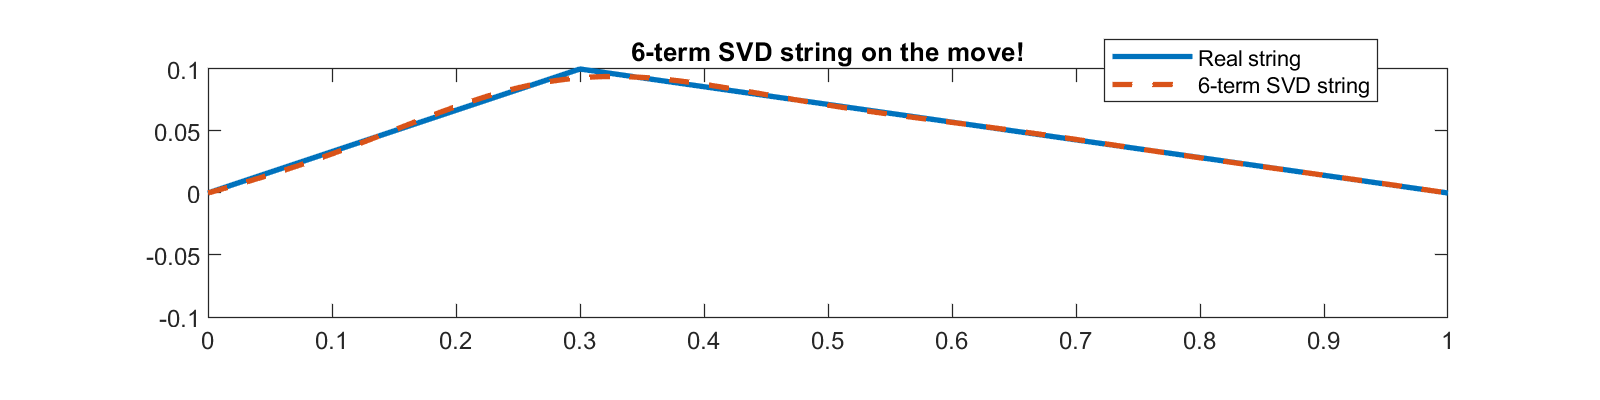

figure('Position', [1 1 800 200])
plt_true = plot(x, Anodamp(:,1), 'LineWidth', 2);
hold on
plt_nu = plot(x, U(:, 1:nu) * c_allframes(:,j), '--', 'LineWidth', 2);
axis image
ylim([-0.1,0.1])
title('6-term SVD string on the move!')
legend('Real string', '6-term SVD string', 'Location', 'best')
pause(1)
for j = [1:4:size(Anodamp, 2) 1] % plot every 4th frame
    plt_true.YData = Anodamp(:,j);
    plt_nu.YData = U(:, 1:nu) * c_allframes(:,j);
    drawnow
end

So what actually *are* these special columns in $U$ that can do such a good job at representing our string no matter what snapshot in time we choose?  I think it's about time we actually *plotted* these left singular vectors to see what they look like.

Remember, columns of $U$ are $m$-dimensional left singular vectors, the same dimensions as the columns of $A$.  So they represent *something* that we can plot against $x$.

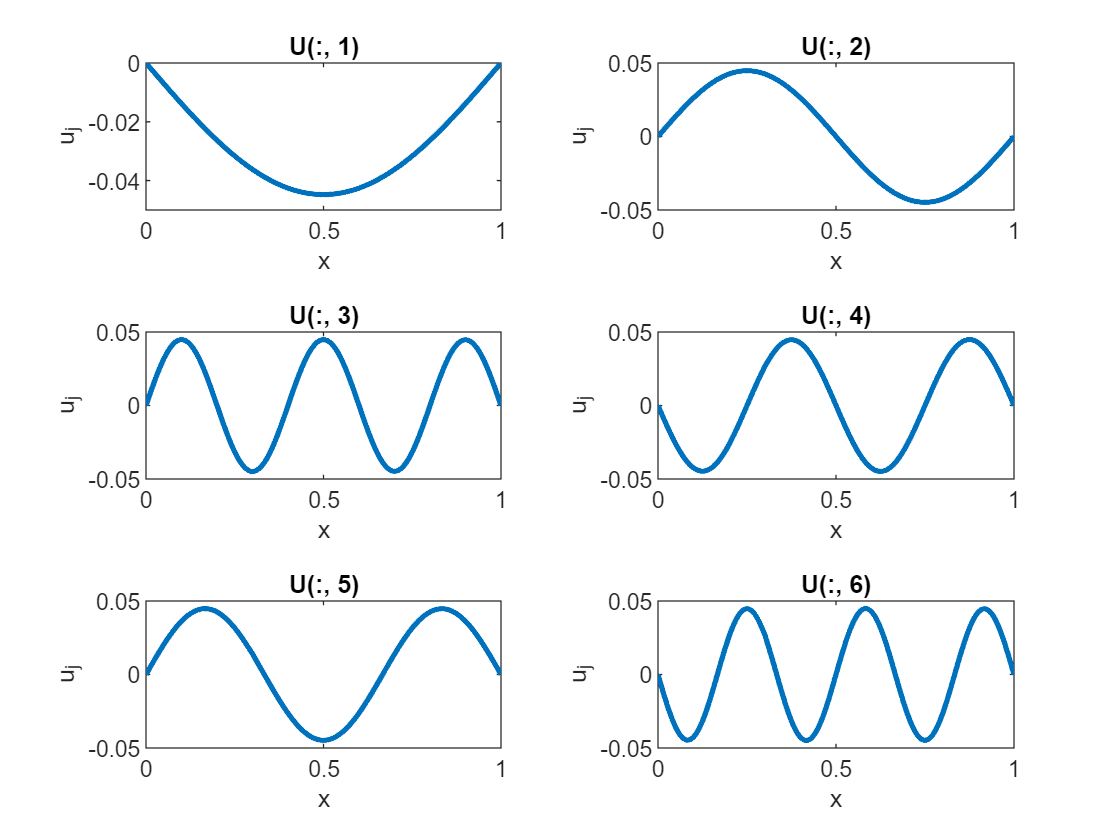

figure
tiledlayout('flow')
for j = 1:6
    nexttile
    plot(x, U(:,j), 'LineWidth', 2)  % plot U(:,j) against x
    xlabel x
    ylabel u_j
    title("U(:, " + j + ")")
end

Good grief, they're sine waves!

Let's try to slowly absorb this revelation.  The *columns of *$U$ *are sine waves*.  $U$.  The matrix $U$ of left singular vectors.  Its columns are sine waves.

Well I can't blame you if this seems a little...inexplicable at first.  Why sine waves, of all things?

But let's think back to what the truncated SVD actually promises: its job is to find the best set of $\nu$ orthonormal basis vectors to approximate every column of $A$. Now for our particular matrix $A$, each column represents a snapshot in time of the profile of a vibrating string.  So for some reason, it seems that sine waves are the most efficient(?)/compact(?)/physically correct(?) way of describing the vibration of a string with only a few terms.

Well, if Joseph Fourier had had the SVD at his disposal, he might well have stumbled on his eponymous Fourier series by performing our little experiment.¹  Because it is indeed the case that the physics of a vibrating string is intimately connected with sine waves (which explains why musical instruments can be made out of vibrating strings).

In fact, the animation of the vibrating string we've been watching was constructed by solving the *wave equation,* a very famous partial differential equation


$$\frac{\partial^2 y}{\partial t^2} =\frac{\partial^2 y}{\partial x^2} $$


whose exact solution is precisely a superposition of sine waves (as you'll learn about if you take MXB322).


$$y(x,t) = \sum_{n=1}^\infty a_n(t) \sin(n\pi x).$$


The coefficients $a_n(t)$ out in front of the sine waves vary with time, which gives the string its motion.  But at any snapshot in time $t^*$, the coefficients $a_n(t^*)$ are just some fixed values, and so the string at time $t^*$ is really just a linear combination of sine waves.

Crucially, the magnitudes of the coefficients $a_n(t)$ die off for large values of $n$.  So it's *physically* true that only a handful of sine waves are really important in constructing the string profile at any time.²

But nobody told the SVD that!  It figured all of this out for itself.  (This is entirely analogous to the revelation that the SVD can learn for itself that the presence or absence of a moustache is a good differentiator of human faces.)

Well if you ever wanted to be impressed by the SVD, take a look at how well it has nailed this problem.

From PDE theory, the first six coefficients $a_n$ (normalised so that $a_1$ is unity) come out to be the following:

an(1:6) % loaded from the workspace

ans =     1.0000    0.2939    0.0424   -0.0454   -0.0494   -0.0202


Whereas our first 6 singular vectors (also normalised) are

sigma(1:6)' / sigma(1)

ans =     1.0000    0.2939    0.0494    0.0454    0.0424    0.0202


They're spot on!  What's more, the SVD has even sorted the coefficients in descending order for us.  That explains why the sine waves we plotted earlier weren't quite in the order of decreasing wavelength.  The SVD noticed that there's slightly more of the $\sin(5\pi x)$ wave in our string than there is $\sin(3\pi x)$ or $\sin(4\pi x)$, so it ordered the sine waves in $U$ so that those with largest coefficients came first.  Amazing!

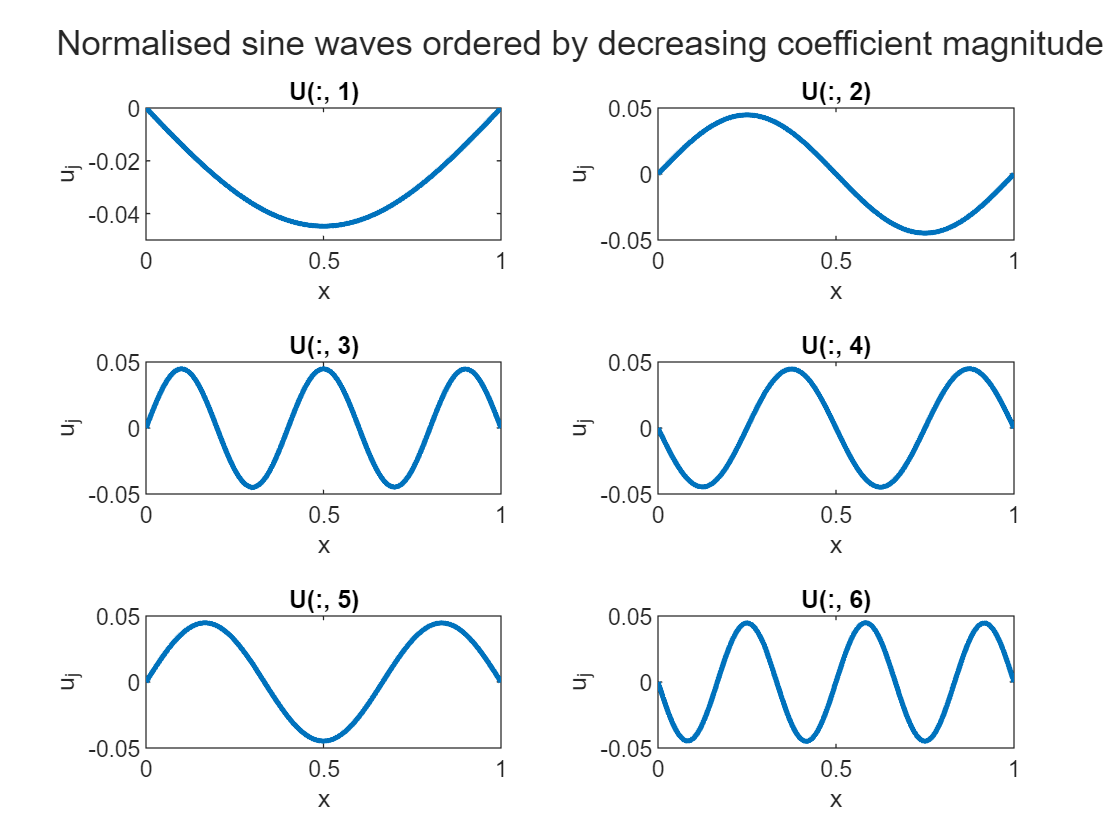

sgtitle('Normalised sine waves ordered by decreasing coefficient magnitude')

## **Now it's time to run**

Let's now return to the more realistic, damped string.  You can rewatch the animation at the start of the worksheet.  Here we illustrate the string at snapshots in time where it's at its maximum displacement.

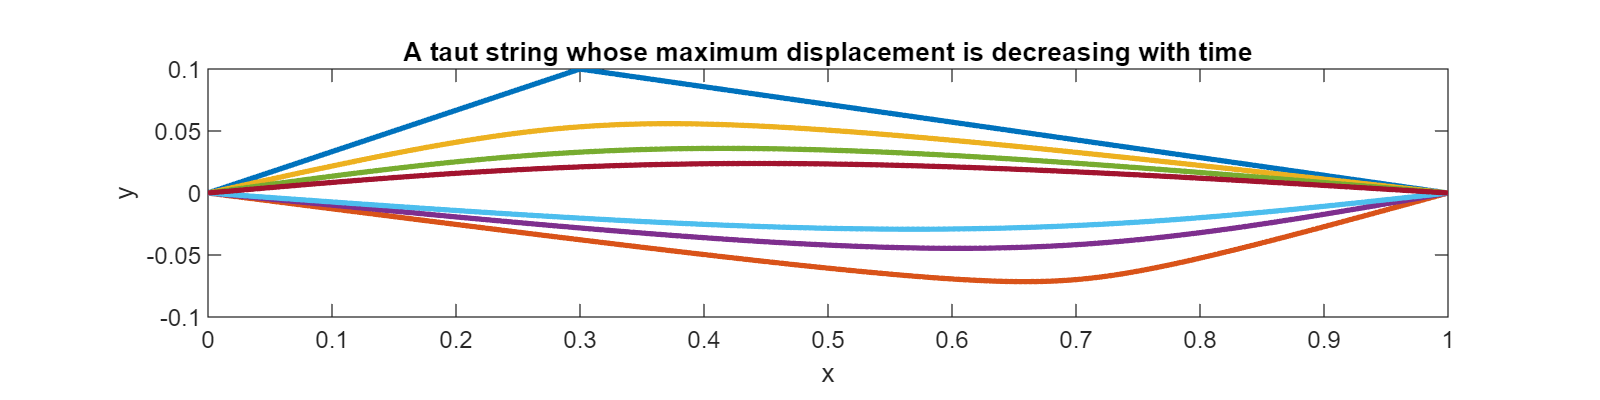

figure('Position', [1 1 800 200])
plt = plot(x, Adamp(:,[1:100:501 600]), 'LineWidth', 2);
axis image
ylim([-0.1,0.1])
title('A taut string whose maximum displacement is decreasing with time')
xlabel x, ylabel y

The string is losing energy over time, so it gradually damps out entirely.  Notice that this means its overall shape is asymmetrically biased over time: it's always higher on the left than it is lower on the right (e.g. its highest extremity is $y = 0.1$ at $x = 0.3$, whereas its lowest extremity is only about $y = -0.07$ at about $x = 0.68$.

Now it's over to you.  See what the SVD makes of the problem this time for the matrix `Adamp`.  What are the columns of $U$ that the SVD comes up with?  Are they still sine waves?  Should they be?  How well does the sum of the first 6 terms approximate the string at different times?

% code to find SVD and plot first 6 columns of U
[U1, Sigma1, V1] = svd(Adamp, 'econ');

c1_allframes = Sigma1(1:nu, 1:nu) * V1(:, 1:nu)'  % coordinate vectors of every column of A

c1_allframes =    -1.7485   -1.7381   -1.7303   -1.7208   -1.7096   -1.6968   -1.6824   -1.6663   -1.6486   -1.6294   -1.6086   -1.5863   -1.5626   -1.5373   -1.5107   -1.4826   -1.4532   -1.4225   -1.3905   -1.3572   -1.3227   -1.2871   -1.2503   -1.2124   -1.1735   -1.1336   -1.0927   -1.0509   -1.0082   -0.9647   -0.9205   -0.8755   -0.8298   -0.7835   -0.7366   -0.6892   -0.6413   -0.5929   -0.5442   -0.4951   -0.4457   -0.3961   -0.3464   -0.2965   -0.2465   -0.1964   -0.1464   -0.0964   -0.0466    0.0031
   -0.5010   -0.4930   -0.4860   -0.4771   -0.4664   -0.4538   -0.4396   -0.4236   -0.4061   -0.3871   -0.3667   -0.3449   -0.3219   -0.2978   -0.2727   -0.2467   -0.2199   -0.1924   -0.1644   -0.1359   -0.1070   -0.0780   -0.0488   -0.0197    0.0093    0.0381    0.0664    0.0944    0.1217    0.1484    0.1742    0.1992    0.2232    0.2462    0.2680    0.2886    0.3079    0.3259    0.3424    0.3575    0.3710    0.3830    0.3934    0.4021    0.4092    0.4147    0.4184    0.4205    

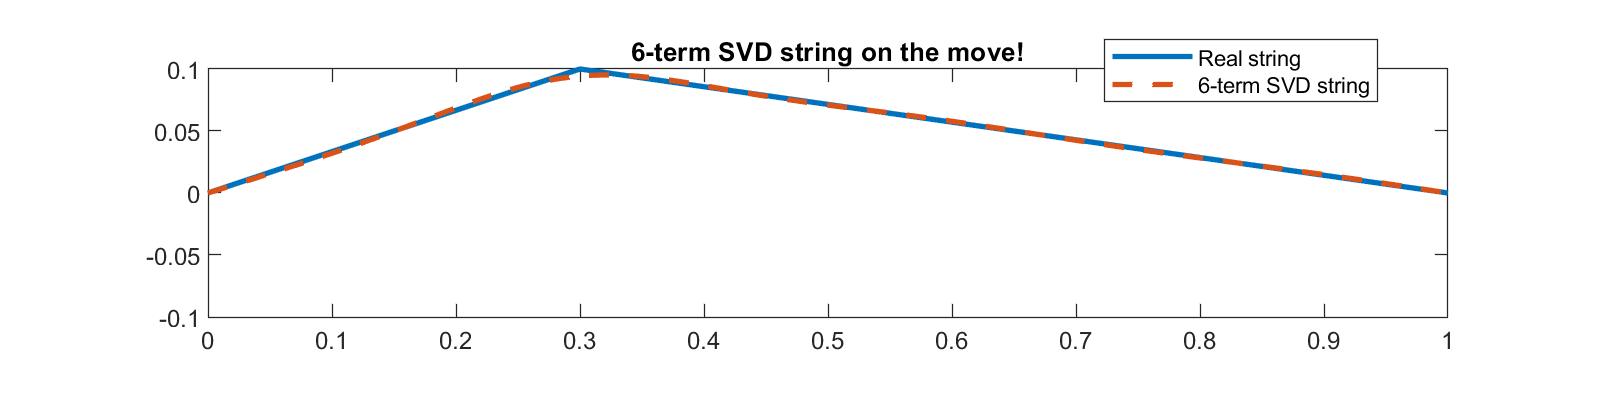

figure('Position', [1 1 800 200])
plt_true_damp = plot(x, Adamp(:,1), 'LineWidth', 2);
hold on
plt_nu_damp = plot(x, U1(:, 1:nu) * c1_allframes(:,j), '--', 'LineWidth', 2);
axis image
ylim([-0.1,0.1])
title('6-term SVD string on the move!')
legend('Real string', '6-term SVD string', 'Location', 'best')
pause(1)
for j = [1:4:size(Adamp, 2) 1] % plot every 4th frame
    plt_true_damp.YData = Adamp(:,j);
    plt_nu_damp.YData = U1(:, 1:nu) * c1_allframes(:,j);
    drawnow
end

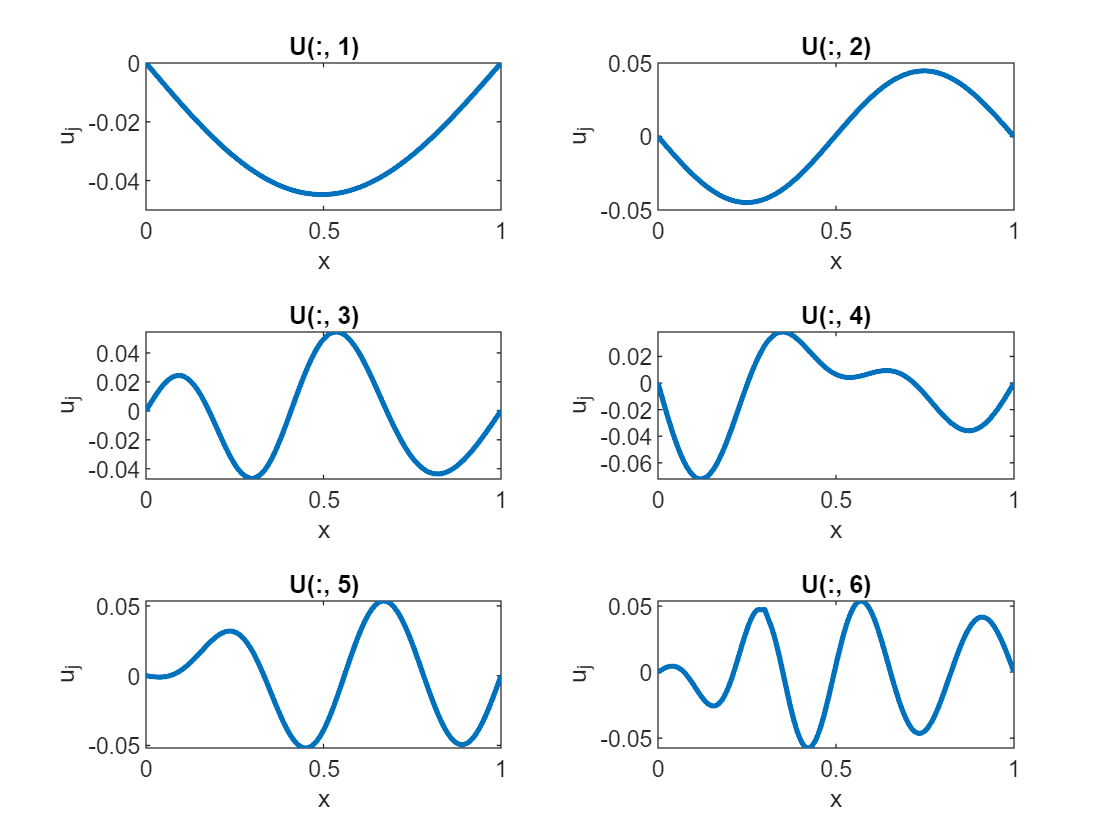

figure
tiledlayout('flow')
for j = 1:6
    nexttile
    plot(x, U1(:,j), 'LineWidth', 2)  % plot U1(:,j) against x
    xlabel x
    ylabel u_j
    title("U(:, " + j + ")")
end

## Comparison to Part II of group project

This analysis of string profiles is entirely analogous to the analysis of human faces in Part II of the group project.  Whereas in this worksheet each column of $A$ represents a one-dimensional string profile, in the project each column of $A$ represents a two-dimensional greyscale image.  But once the data has been loaded into the matrix, the SVD doesn't care at all where it came from.

In the project, analogous to what we found in this worksheet, you should find that only a small number of "eigenfaces" (once again, columns of $U$, i.e. left singular vectors) are required to represent *any* human face in the dataset to good accuracy.

In the string example, the columns of $U$ turned out to be sine waves, telling us something fundamental about the physics behind the data.  In the eigenface example, the columns of $U$ will look just like human faces with particular features emphasised, e.g a moustache.  In both cases, the SVD is uncovering the essence of how to represent the data in the most compact way.  In doing so, it's highlighting the main *features* of the data.  By projecting the actual data onto this low-dimensional *feature space*, you are getting a very compact but still highly accurate representation of the data, e.g. in the string example, each string profile is really just composed of a handful of sine waves.

But in the damped string example, you should have found that the basis vectors weren't just pure sine waves any more.  That's because the SVD discovered that it could "exploit" the asymmetry of the data we provided, to get a more efficient representation in terms of lopsided basis functions.  In some sense, it was too clever for its own good there, because the lopsidedness was really an artefact of the data we happened to provide, rather than anything fundamental to the physics.  Had we chosen another initial condition (e.g. pulled the string up at $x = 0.7$ instead), it would have come out lopsided the other way around.  But there's nothing truly lopsided in the physics: it's really just sine waves no matter what.

The moral of the story?  The SVD works (only) on the data you give it.  If it can exploit any aspect of that data to get a more efficient representation, that's what it will do.  You need to ensure your data are representative of the true population you're trying to learn about, to ensure it's not taking any cheeky shortcuts that might mislead you.

## Just for fun

It's instructive to plot the approximations of the string using just one term of the SVD, then just two terms, then just three terms, etc.  This could be for the whole animation, or just at one snapshot in time, say at the bottom of the first cycle.

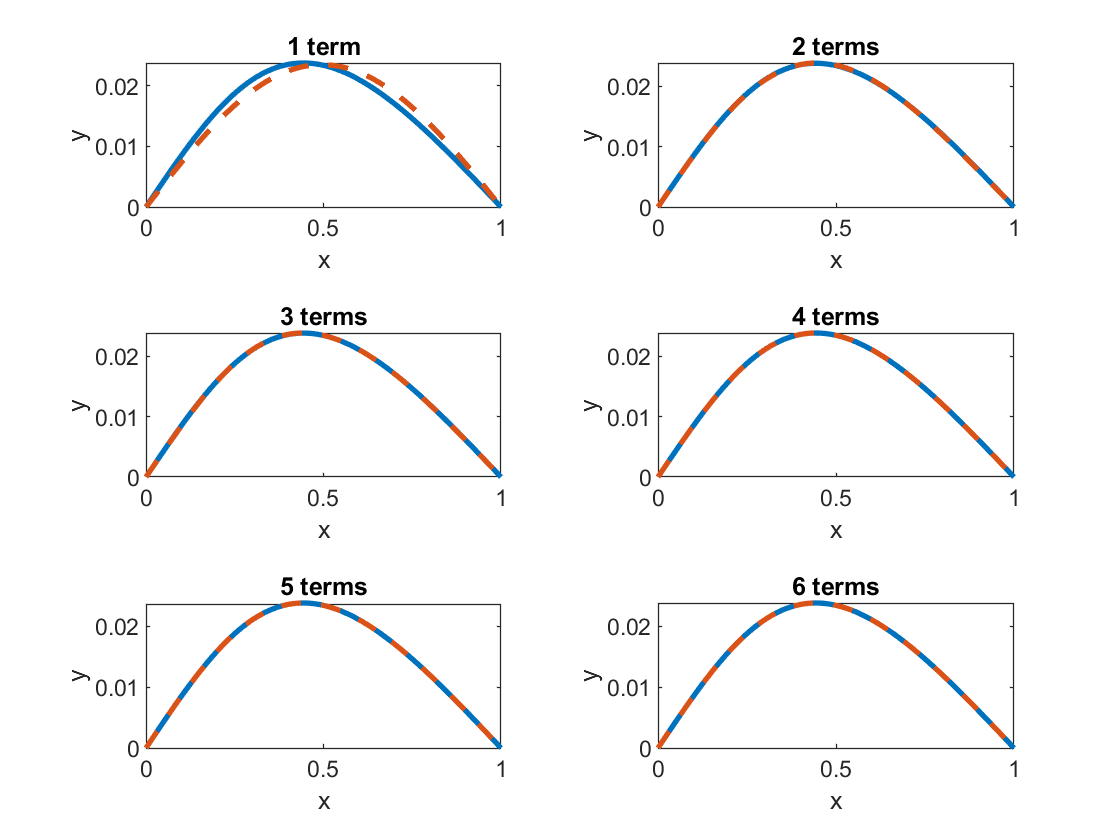

figure
tiledlayout('flow')
nexttile
true_damped_list = plot(x, Adamp(:, 1), 'LineWidth', 2);
hold on
approx_damped_list = plot(x, U1(:, 1) * Sigma(1, 1) * V(1, 1)', '--', 'LineWidth', 2);

xlabel x
ylabel y
title("1 term")

for i = 2:6
    nexttile
    true_damped_list(i) = plot(x, Adamp(:, 1), 'LineWidth', 2);
    hold on
    approx_damped_list(i) = plot(x, U1(:, 1:i) * Sigma1(1:i, 1:i) * V1(1, 1:i)', '--', 'LineWidth', 2);

    xlabel x
    ylabel y
    title(num2str(i) + " terms")
end
for t = 1:size(Adamp, 2)
    for i = 1:6
        true_damped_list(i).YData = Adamp(:, t);
        approx_damped_list(i).YData = U1(:, 1:i) * Sigma1(1:i, 1:i) * V1(t, 1:i)';
    end
    drawnow
end

This is analogous to watching how a reconstructed face evolves as it's built using just one eigenface, then just two, and so on.  It can be quite fun to watch (much moreso for faces than for strings).

**Footnotes**

1. Not really of course!  It wasn't until 1970 that an efficient algorithm for computing the SVD was invented, and we've only had powerful enough computers to do this example on a laptop since the last decade or two.

2. This is because the *Fourier series* for a continuous function has coefficients that decay with increasing $n$.